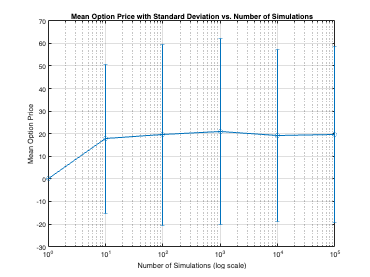

% Parameters
S0 = 350;             % Current stock price
K = S0 + 20;          % Strike price
r = 0.05;             % Risk-free interest rate
sigma = 0.6802;       % Volatility from previous section
T = 1/12;             % Time to maturity in years (1 month)
num_steps = 100;      % Number of time steps in each simulation
dt = T / num_steps;   % Time increment

% Define the different simulation sizes
simulation_sizes = [1, 10, 100, 1000, 10000, 100000];
mean_prices = zeros(size(simulation_sizes));
std_devs = zeros(size(simulation_sizes));

% Run simulations for each sample size
for idx = 1:length(simulation_sizes)
    num_simulations = simulation_sizes(idx);
    end_prices = zeros(num_simulations, 1);
    
    % Monte Carlo simulation for each sample size
    for i = 1:num_simulations
        path = zeros(num_steps, 1);
        path(1) = S0;
        
        for t = 2:num_steps
            Z = randn; % Standard normal random variable
            path(t) = path(t-1) * exp((r - 0.5 * sigma^2) * dt + sigma * sqrt(dt) * Z);
        end
        
        end_prices(i) = path(end);
    end
    
    % Calculate the option payoffs and statistics
    payoffs = max(end_prices - K, 0);
    mean_prices(idx) = exp(-r * T) * mean(payoffs); % Mean option price
    std_devs(idx) = exp(-r * T) * std(payoffs);      % Standard deviation of option price
end

% Plot mean option price with standard deviation as error bars
figure;
errorbar(simulation_sizes, mean_prices, std_devs, 'o-');
set(gca, 'XScale', 'log'); % Log scale for x-axis
title('Mean Option Price with Standard Deviation vs. Number of Simulations');
xlabel('Number of Simulations (log scale)');
ylabel('Mean Option Price');
grid on;